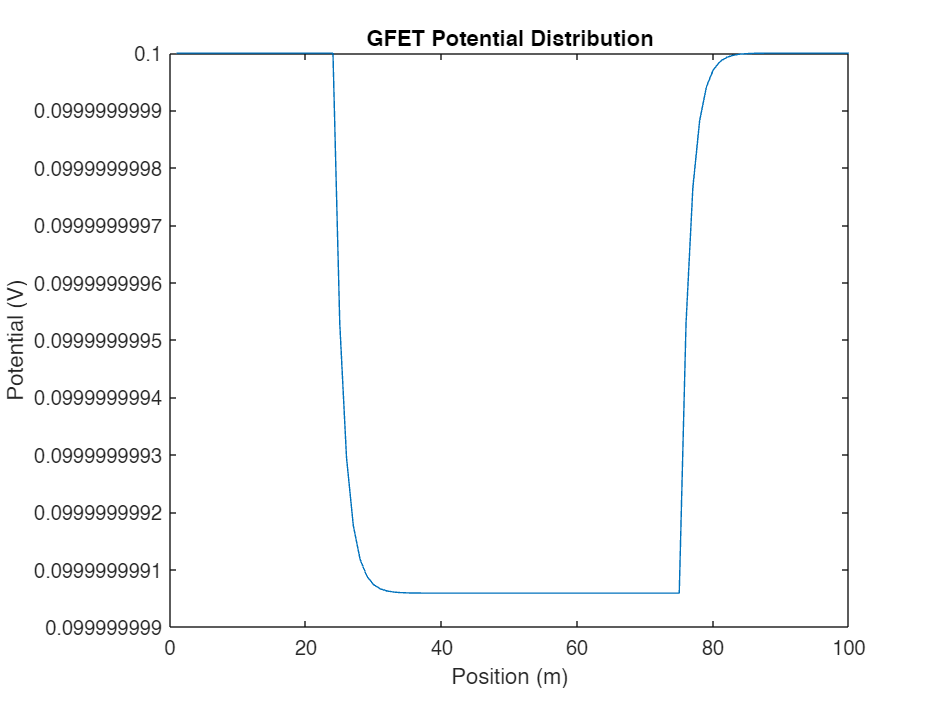

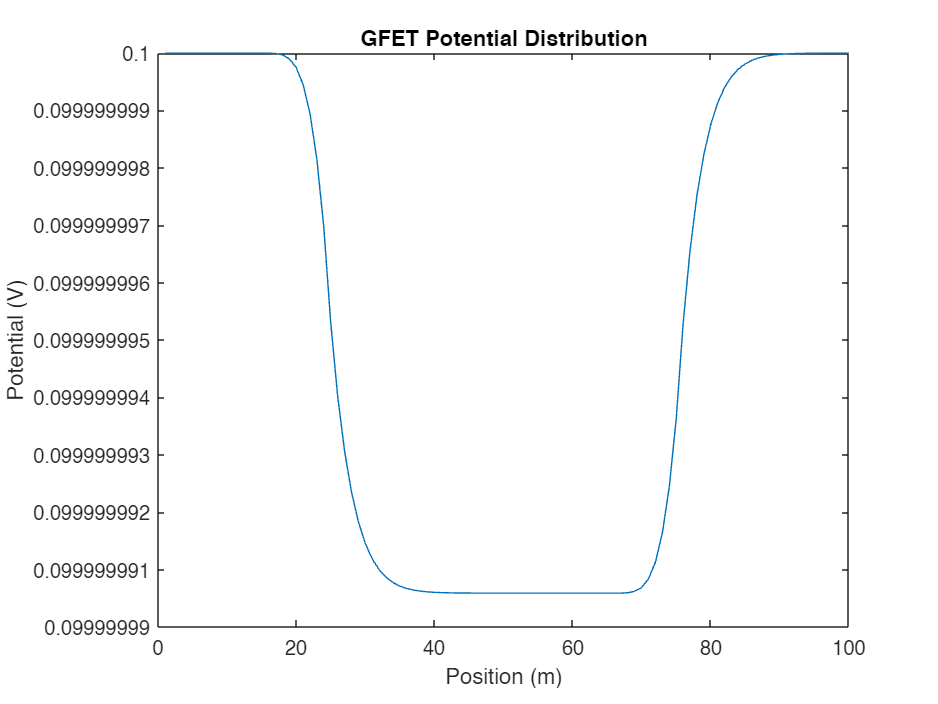

% Graphene Field-Effect Transistor (GFET) DNA Detection Simulation

% Constants and Parameters
epsilon0 = 8.854e-12;        % Vacuum permittivity
epsilon_G = 6;               % Dielectric constant of graphene
q = 1.6e-19;                 % Electron charge
kB = 1.38e-23;               % Boltzmann constant
T = 300;                     % Temperature (Kelvin)
L = 100e-9;                  % Channel length (m)
W = 100e-9;                  % Channel width (m)
h = 1e-9;                    % Simulation step size (m)
N = round(L/h);              % Number of simulation steps
phi0 = 0.1;                  % Initial potential (V)
mu = 0.01;                   % Mobility (m^2/Vs)
DNA_charge = -2*q;           % DNA molecule charge (C)
DNA_radius = 1.5e-9;         % DNA molecule radius (m)
DNA_concentration = 1e-6;    % DNA concentration (mol/m^3)
k_on = 1e-9;                 % Association rate constant (m^3/mol/s)
screening_length = 5e-9;     % Screening length (m)
source_voltage = 0.1;        % Source voltage (V)
VDS = 0.1;                   % Drain-Source voltage (V)

% Define Gate voltage distribution
VG = zeros(N, 1);
VG(N/4:3*N/4) = 0.1;         % Gate voltage applied to the GFET region (V)

% Initialize potential and charge density arrays
phi = ones(N, 1) * phi0;     % Electrostatic potential (V)
rho = zeros(N, 1);           % Charge density (C/m^3)

% Create DNA molecule positions matrix
numMolecules = 10;            % Number of DNA molecules
x_positions = L * rand(numMolecules, 1);
y_positions = W * rand(numMolecules, 1);

% Create a figure to display the movie
figure;
axis tight manual;
set(gcf, 'Position', [100, 100, 800, 600]);
movieFrames(numMolecules) = struct('cdata', [], 'colormap', []);

for i = 1:numMolecules
    % Update DNA positions
    x_positions(i) = L * rand();
    y_positions(i) = W * rand();
    
    % Reset charge density array
    rho = zeros(N, 1);
    
    % Calculate charge density due to DNA molecules
    for j = 1:numMolecules
        dist = sqrt((x_positions(j) - (1:N)*h).^2 + (y_positions(j) - W/2).^2);
        rho = rho + DNA_charge * DNA_concentration * (dist <= DNA_radius);
    end
    
    % Solve Poisson equation iteratively
    maxIterations = 1000;       % Maximum number of iterations
    tolerance = 1e-6;           % Convergence tolerance
    delta = 1;                 % Initial change in potential
    
    iter = 0;
    while delta > tolerance && iter < maxIterations
        delta = 0;
        for j = 2:N-1
            % Calculate screening effect
            rho_eff = rho(j);
            V_screening = -rho_eff * screening_length^2 / (2 * epsilon0 * epsilon_G);
            
            % Calculate thermionic emission current
            phi_bar = (phi(j-1) + phi(j+1)) / 2;
            I_thermionic = q * mu * W * source_voltage * exp(-q * phi_bar / (kB * T));
            
            % Update potential
            phi_new = (phi(j-1) + phi(j+1) - h^2 * (rho(j) + VG(j) + V_screening) / (2 * epsilon0 * epsilon_G)) / 2;
            delta = max(delta, abs(phi_new - phi(j)));
            phi(j) = phi_new;
        end
        iter = iter + 1;
    end
    
    % Calculate Drain-Source Current (IDS)
    IDS = zeros(N, 1);
    for j = 2:N-1
        phi_bar = (phi(j-1) + phi(j+1)) / 2;
        IDS(j) = q * mu * W * (phi(j) - phi_bar) / h;
    end
    
    % Plot the potential distribution
   
    plot(phi);
    xlabel('Position (m)');
    ylabel('Potential (V)');
    title('GFET Potential Distribution');
    

    
    % Capture the current frame
    movieFrames(i) = getframe(gcf);
end

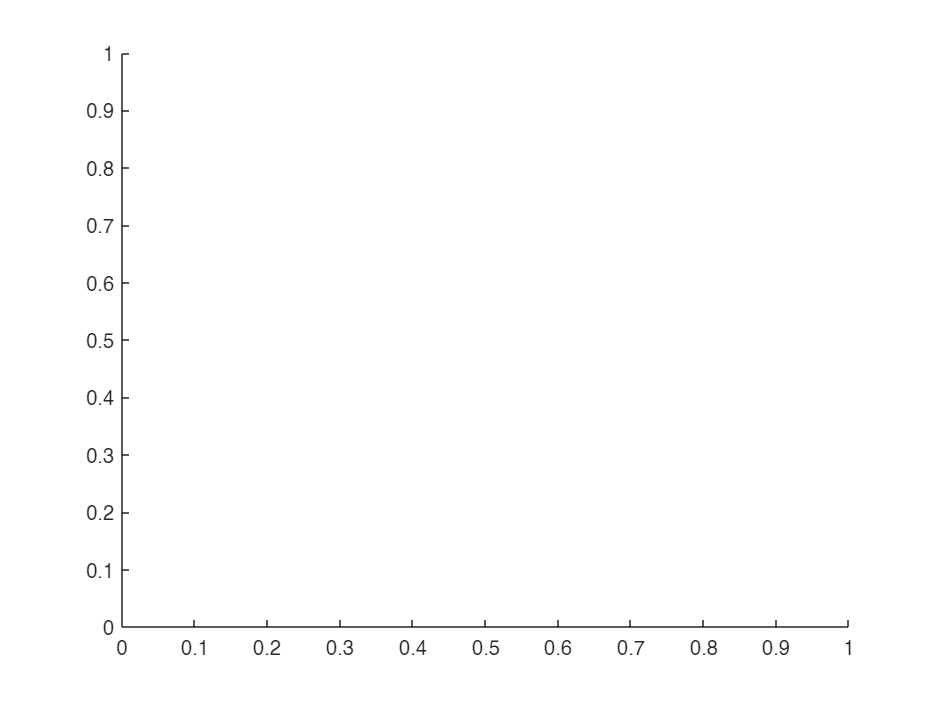


% Play the movie
figure;
axis tight manual;
set(gcf, 'Position', [100, 100, 800, 600]);
movie(movieFrames, 10);